# MAE 232A: FINAL PROJECT

#### **By** - Nandan Seshadri (A59018150)

close; clc; clear;

## Pre-processing

### `Preprocessing: Inputs`

[nEle, NEN, nNodes] = Input();

### `Preprocessing: Discretization`

x_minmax = [0, 1]; % domain x min and max
y_minmax = [0, 1]; % domain y min and max
domain = [x_minmax; y_minmax];

[nodes2D,elements2D] = mesh(nNodes, x_minmax, y_minmax);
n_nodes = size(nodes2D,1);
n_ele = size(elements2D,1);
ele_idx = (1:length(elements2D));  % Number of elements
ele_mat = reshape(ele_idx, nEle, nEle)'; % Assemble elements as a mesh
LM = [ele_idx' elements2D];
Inds = zeros(nEle,2);
L=x_minmax(2);
x=x_minmax(1);

node_idx = [(1:nNodes^2)' nodes2D];

nodes=zeros(nEle+1,1);

n = (nEle+1);

% nodal coordinates 
for iN=2:nEle+1 %first node is zero.
    x=x+L/nEle;
    nodes(iN,1)=x;
end

Length = zeros(nEle,1);
elements = zeros(nEle,2);
for iE=1:nEle
    st_pt=nodes(iE,1);
    end_pt=nodes(iE+1,1);
    elements(iE,:)=[st_pt,end_pt];
    st_pt=elements(nEle,1);%coordinate of starting pt of element.
    end_pt=elements(nEle,2);%coordinate of end pt.
    l_e=norm(end_pt - st_pt);%length of element.
end

% data for gauss integration of order 2.
nGP = 2; %2x2 integration.
IP = [-1/sqrt(3),1/sqrt(3)];
WT = [1 1];

## Processing

### `Processing: Stiffness Matrix and Force Vector Evaluation and Assembly`

% Initialize global stiffness matrix and force vector
K_global = zeros(nNodes^2);
f_b_global = zeros(nNodes^2,1);
f_h_global = zeros(nNodes^2,1);

for e=1:n_ele    
%     nodal information
    NID = elements2D(e,:);
    nodes = nodes2D(elements2D(e,:),:);% nodal coordinates for the element
    X = nodes(:,1);
    Y = nodes(:,2);

    xI = 1:nNodes;
    % Gather Nodal Information
    node1 = elements2D(e,2); % Node numbers
    node2 = elements2D(e,3);
    
%     stiffness and force arrays
    % Initializing: 
    K_local = zeros(NEN); %Element stiffnesss matrix
    f_b_local = zeros(NEN,1); % force vector for body force
    f_h_local = zeros(NEN,1);
    Fh3 = zeros(NEN,1); %force vector for right boundary condition
    Fh4 = zeros(NEN,1); %force vector for top boundary condition
    for i = 1:nGP
        for j = 1:nGP
            xi = IP(i); 
            eta = IP(j);         
            [N,B,A] = NBAmat(1,xi,eta,X,Y);
            Jv = det(A);
            x = N*X; y = N*Y; % x and y in-terms of xi and eta.
            b = (x^2 + y^2)*exp(x*y); %body force term.
            K_local = K_local + (B')*B*Jv*WT(i)*WT(j);
            f_b_local = f_b_local + (-(N')*b*Jv*WT(i)*WT(j));   
         end
    end
    
    global_ycoord = nodes2D(:, 2);
    global_xcoord = nodes2D(:, 1);
    local_coord = zeros(NEN,1);
    gamma3_ele = (ele_mat(:,end));
    gamma4_ele = (ele_mat(end,:))';
        if ismember(e,gamma3_ele)
            Global_list = elements2D(e,:);
            Global_coord = 0;
            for jj = 1:length(Global_list)
                global_coord = Global_list(jj);
                local_coord(jj) = global_ycoord(global_coord);
            end
            y = local_coord';
            for i=1:length(IP)
                gauss1 = 1; %Xi
                gauss2 = IP; %n
                [N_h3,B3,Js3] = NBAmat(1,gauss1,gauss2(i),X',y);
                y_h3 = sum(N_h3 .* y);
                js3 = norm([Js3(2,2),Js3(2,1)]);
                h3 = y_h3*exp(y_h3);
                Fh3 = Fh3 + (N_h3' * h3 .* js3);
            end
        else
            Fh3 = zeros(NEN, 1);                
        end
        if ismember(e,gamma4_ele)
            Global_list = elements2D(e,:);
            Global_coord = 0;
            for jj = 1:length(Global_list)
                global_coord = Global_list(jj);
                local_coord(jj) = global_xcoord(global_coord);
            end
            x = local_coord';
            for i = 1:length(IP)              
                gauss1 = IP;
                gauss2 = 1;
                [N_h4,B4,Js4] = NBAmat(1,gauss1(i),gauss2(1),x,Y);
                x_h4 = sum(N_h4 .* x);
                js4 = norm([Js4(2,2),Js4(2,1)]);
                h4 = x_h4*exp(x_h4);
                Fh4 = Fh4+(N_h4' .* h4 .* js4);
            end
        else
                Fh4 = zeros(NEN, 1);       
        end
    f_h_local = f_h_local + Fh3 + Fh4;
    
    % Assembly, Map local to global
    % Global matrix    
    for row=1:4      
        for col=1:4
            K_global(NID(row),NID(col))=K_global(NID(row),NID(col))+K_local(row,col); % K_global
        end
        f_b_global(NID(row))=f_b_global(NID(row))+f_b_local(row);   % f_b_global
        f_h_global(NID(row))=f_h_global(NID(row))+f_h_local(row);   % f_h_global
    end
    f_global = f_b_global + f_h_global;

    % Matrix reduction
    bcDv = 1;
    dirichlet1 = (1:nEle+1)'; % global node for prescribing u as bc.
    dirichlet2 = (1:nEle+1:n_nodes-(nEle))'; % global node for prescribing u as bc.
    dirichlet = union(dirichlet1, dirichlet2);
    K_ng = K_global; % to manipulate to solve
    f_ng = f_global;
    u_b = 1.0;
    for i = 1:length(dirichlet)
        j = dirichlet(i);
        f_ng = f_ng - bcDv * K_ng(:,j);
        K_ng(j,:) = 0;
        K_ng(:,j) = 0;
        K_ng(j,j) = 1;
        f_ng(j) = bcDv;
    end
    u_app = K_ng\f_ng; % Solve for nodal coefficients u
    uh_plot = reshape(u_app, nNodes, nNodes);
end

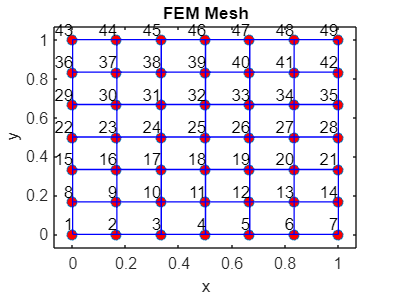


xp = linspace(x_minmax(1), x_minmax(2), nEle+1);
yp = linspace(y_minmax(1), y_minmax(2), nEle+1);
[x, y] = meshgrid(xp, yp);

% Flatten the meshgrid arrays
x_flat = x(:);
y_flat = y(:);
% Plotting the mesh and numbering nodes
plot(x_flat, y_flat, 'o', 'MarkerFaceColor', 'r'); % Plot nodes
hold on;
% Draw the grid lines
for i = 1:size(x, 1)
    plot(x(i, :), y(i, :), 'b');
end
for j = 1:size(y, 2)
    plot(x(:, j), y(:, j), 'b');
end
for i = 1:length(x_flat)
    text(y_flat(i), x_flat(i), sprintf('%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
delta = 0.07;
axis([(x_minmax(1)-delta) (x_minmax(2)+delta) (y_minmax(1)-delta) (y_minmax(2)+delta)]);
title('FEM Mesh');
xlabel('x');
ylabel('y');
grid off
hold off


% Obtain the values on y = 0.5
if nEle == 2
    uh_edit = uh_plot(2,:);
elseif nEle == 6
    uh_edit = uh_plot(4,:);
elseif nEle ==12
    uh_edit = uh_plot(7,:);
elseif nEle ==24
    uh_edit = uh_plot(13,:);
end

## `Results`

disp(['Elemental stiffness: K^',num2str(e),'='])

Elemental stiffness: K^36=


disp(K_global)

  Columns 1 through 18

    0.6667   -0.1667         0         0         0         0         0   -0.1667   -0.3333         0         0         0         0         0         0         0         0         0
   -0.1667    1.3333   -0.1667         0         0         0         0   -0.3333   -0.3333   -0.3333         0         0         0         0         0         0         0         0
         0   -0.1667    1.3333   -0.1667         0         0         0         0   -0.3333   -0.3333   -0.3333         0         0         0         0         0         0         0
         0         0   -0.1667    1.3333   -0.1667         0         0         0         0   -0.3333   -0.3333   -0.3333         0         0         0         0         0         0
         0         0         0   -0.1667    1.3333   -0.1667         0         0         0         0   -0.3333   -0.3333   -0.3333         0         0         0         0         0
         0         0         0         0   -0.1667    1.3333   -0.1667 

disp(['Force vector: f^',num2str(e),'='])

Force vector: f^36=


disp(f_global)

   -0.0001
   -0.0005
   -0.0017
   -0.0037
   -0.0065
   -0.0103
   -0.0015
   -0.0005
   -0.0019
   -0.0044
   -0.0087
   -0.0150
   -0.0235
    0.0187
   -0.0017
   -0.0044
   -0.0073
   -0.0123
   -0.0198
   -0.0301
    0.0595
   -0.0037
   -0.0087
   -0.0123
   -0.0184
   -0.0276
   -0.0406
    0.1132
   -0.0065
   -0.0150
   -0.0198
   -0.0276
   -0.0394
   -0.0562
    0.1831
   -0.0103
   -0.0235
   -0.0301
   -0.0406
   -0.0562
   -0.0788
    0.2731
   -0.0015
    0.0187
    0.0595
    0.1132
    0.1831
    0.2731
    0.3753



disp(['fb^',num2str(e),'='])

fb^36=


disp(f_b_global)

   -0.0001
   -0.0005
   -0.0017
   -0.0037
   -0.0065
   -0.0103
   -0.0066
   -0.0005
   -0.0019
   -0.0044
   -0.0087
   -0.0150
   -0.0235
   -0.0151
   -0.0017
   -0.0044
   -0.0073
   -0.0123
   -0.0198
   -0.0301
   -0.0193
   -0.0037
   -0.0087
   -0.0123
   -0.0184
   -0.0276
   -0.0406
   -0.0258
   -0.0065
   -0.0150
   -0.0198
   -0.0276
   -0.0394
   -0.0562
   -0.0353
   -0.0103
   -0.0235
   -0.0301
   -0.0406
   -0.0562
   -0.0788
   -0.0490
   -0.0066
   -0.0151
   -0.0193
   -0.0258
   -0.0353
   -0.0490
   -0.0304



disp(['fh^',num2str(e),'='])

fh^36=


disp(f_h_global)

         0
         0
         0
         0
         0
         0
    0.0050
         0
         0
         0
         0
         0
         0
    0.0338
         0
         0
         0
         0
         0
         0
    0.0788
         0
         0
         0
         0
         0
         0
    0.1390
         0
         0
         0
         0
         0
         0
    0.2184
         0
         0
         0
         0
         0
         0
    0.3221
    0.0050
    0.0338
    0.0788
    0.1390
    0.2184
    0.3221
    0.4057



disp(['Displacement vector: U^h^: ',num2str(e),'='])

Displacement vector: U^h^: 36=


disp(u_app)

    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0284
    1.0574
    1.0871
    1.1175
    1.1486
    1.1802
    1.0000
    1.0574
    1.1178
    1.1815
    1.2486
    1.3193
    1.3937
    1.0000
    1.0871
    1.1815
    1.2839
    1.3950
    1.5154
    1.6459
    1.0000
    1.1175
    1.2486
    1.3950
    1.5583
    1.7405
    1.9436
    1.0000
    1.1486
    1.3193
    1.5154
    1.7405
    1.9988
    2.2951
    1.0000
    1.1802
    1.3937
    1.6459
    1.9436
    2.2951
    2.7099



## **Part 1**

% Using the exact solution to calculate error
syms X_coord_exact
u_exact = exp(X_coord_exact*0.5);
X_coord_exact = linspace(0, 1, nNodes^2);
% Initialize u_sol as an empty vector
% u_sol = zeros(size(u_exact));

## **Part 2**

% Obtaining the derivative of the exact solution
ux_exact = diff(u_exact);

ux_app = zeros(length(uh_edit)-1, 1);  % Allocate space for one less than the length of uh_edit
for j = 1:(length(uh_edit)-1)  % Adjust the loop to avoid going out of bounds
    ux_app(j) = (uh_edit(j+1) - uh_edit(j)) / l_e;
end
ux_app = [ux_app' ux_app(end)]';

## **Part 3**

for ee = 1:nEle^2   % Loop through elements to calculate error
    NIDe = elements2D(ee,:);
    nodese = nodes2D(elements2D(ee,:),:);% nodal coordinates for the element
    Xe = nodese(:,1);
    Ye = nodese(:,2);

    % Gather Nodal Information
    n1 = NIDe(1); % Node numbers
    n2 = NIDe(2);
    n3 = NIDe(3); % Node numbers
    n4 = NIDe(4);
    
    uh_local = [u_app(n1); u_app(n2); u_app(n3); u_app(n4)]; % Indexing global uh to local
    eleSum = 0;
    for i = 1:nGP
        for j = 1:nGP
            xi = IP(i);
            eta = IP(j);         
            [N_err,~,A_err] = NBAmat(1,xi,eta,X,Y);
            Jv = det(A_err);
            uh_node = N_err*uh_local;
            xx_xi = N_err*Xe;       % New shape function gradients for errors wrt xi, eta
            yy_eta = N_err*Ye;
            u_node = exp(xx_xi*yy_eta);
            nodeDiff = (u_node - uh_node).^2*Jv;
            eleSum = eleSum + nodeDiff.* WT(i) .* WT(j);
        end
    end
    eleSum = eleSum + sqrt(eleSum); % Summation of all the errors
end
disp(['The summation of errors: ', num2str(eleSum)])

The summation of errors: 0.00053084


## **Plots**

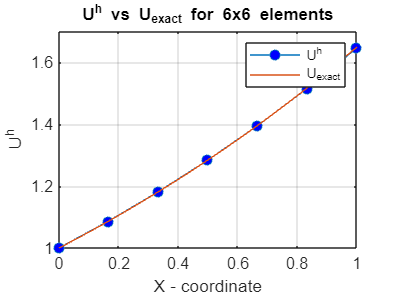

% Plotting mesh results with exact solution
plot(xp, uh_edit, '-o', 'MarkerFaceColor', 'b')
hold on;
fplot(u_exact, [0, 1])
legend("U^h", "U_{exact}")
xlabel("X - coordinate")
ylabel("U^h")
title("U^h vs U_{exact} for "+nEle+ "x" +nEle+ " elements")
grid on
hold off;

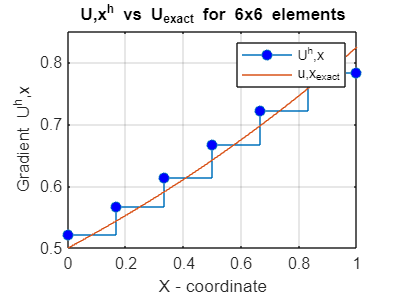


% Plot element-wise
stairs(xp, ux_app, '-o', 'MarkerFaceColor', 'b')
hold on
fplot(ux_exact,[0, 1])
legend("U^h,x", "u,x_{exact}")
xlabel("X - coordinate")
ylabel("Gradient U^h,x")
title("U,x^h vs U_{exact} for "+nEle+ "x" +nEle+ " elements")
grid on
hold off


% Plot errors on log-log scale
errors = [5.3084e-04, 7.4139e-05, 9.8342e-06];  % Noting down errors manually
element_sizes = [1/6, 1/12, 1/24];              % Element dimensions
% Plot the errors on a log-log scale
loglog(element_sizes, errors, '-ro', 'MarkerEdgeColor','b', 'MarkerFaceColor', 'b')
% Calculate the rate of convergence
p = polyfit(log(element_sizes), log(errors), 1);
rateOfConvergence = p(1);
disp(['Rate of Convergence: ', num2str(rateOfConvergence)])

Rate of Convergence: 2.8772


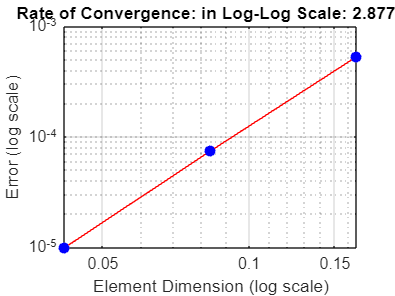

xlabel('Element Dimension (log scale)')
ylabel('Error (log scale)')
title(['Rate of Convergence: in Log-Log Scale: ', num2str(rateOfConvergence)])
grid on

## **Mesh**

function [nodes,elements] = mesh(n,X,Y)
% INPUT: 
    % n: scalar no. of nodes in one row
    % X: array of min and max x coordinates for rectangular domain [x_min x_max]
    % Y: array of min and max y coordinates for rectangular domain [y_min y_max]
% OUTPUT: 
    % nodes: array for nodal coordinates
    % elements: array where i'th row has node numbers pertaining to i'th element.
x = linspace(X(1),X(2),n); % list of all possibe x-coordinates.
y = linspace(Y(1),Y(2),n); % list of all possible y-coordinates.
nodes = zeros((n)^2,2);
elements = zeros((n-1)^2,4);
% NODES
kj = 1; % running variable to account for number of nodes.
for iy=1:n
    for ix=1:n
        % cordinates for the k'th node.
        nodes(kj,1) = x(ix);
        nodes(kj,2) = y(iy);
        kj = kj+1; %next node.
    end
end

% ELEMENTS
i=1; % counter for element ID
for j=1:n-1
    for k=j+((j-1)*(n-1)):(j+((j-1)*(n-1)))+(n-2)
        elements(i,:) = [k,k+1,k+n+1,k+n];
        i=i+1;
    end
end
end

## Shape functions

function [N,B,A] = NBAmat(n,xi,eta,x,y) 
% Inputs: 
    % n: order
    % xi: int point in xi [1xNINT]
    % eta: int point in eta [1xNINT]
    % x: array of x-coordinate [1x4]
    % y: array of y-coordinate [1x4]
% Outputs: 
    % N: shape function vector for a Q4 element [1x4]
    % B: B matrix for a Q4 element [2x4]
    % A: A matrix for a Q4 element [2x2]
    
    switch n
        case 1
            N = (1/4)*[(1-xi)*(1-eta),(1+xi)*(1-eta),(1+xi)*(1+eta),(1-xi)*(1+eta)];
            dxdxi = (1/4)*(-(1-eta)*x(1)+(1-eta)*x(2)+(1+eta)*x(3)-(1+eta)*x(4));
            dxdeta = (1/4)*(-(1-xi)*x(1)-(1+xi)*x(2)+(1+xi)*x(3)+(1-xi)*x(4));
            dydxi = (1/4)*(-(1-eta)*y(1)+(1-eta)*y(2)+(1+eta)*y(3)-(1+eta)*y(4));
            dydeta = (1/4)*(-(1-xi)*y(1)-(1+xi)*y(2)+(1+xi)*y(3)+(1-xi)*y(4));
            dNdxi = (1/4)*[-(1-eta),(1-eta),(1+eta),-(1+eta)];
            dNdeta = (1/4)*[-(1-xi),-(1+xi),(1+xi),(1-xi)];
            A = [dxdxi,dydxi;dxdeta,dydeta];
            B = A\[dNdxi; dNdeta];
            
        otherwise
            disp('Not Available')
    end
end

## `Input function`

function [nEle, NEN, nNodes] = Input()
% Outputs:
    % nEle = number of elements
    % Omega = 1x2 array of domain position [m]

% Mesh
nEle = 6;   % Number of finite elements = 6
% nEle = 12;  % Number of finite elements = 12
% nEle = 24;  % Number of finite elements = 24

NEN = 4; % Number of element nodes
nNodes = nEle + 1;

end